## 2D rotations

Points can be rotated through an angle θ about the origin. 

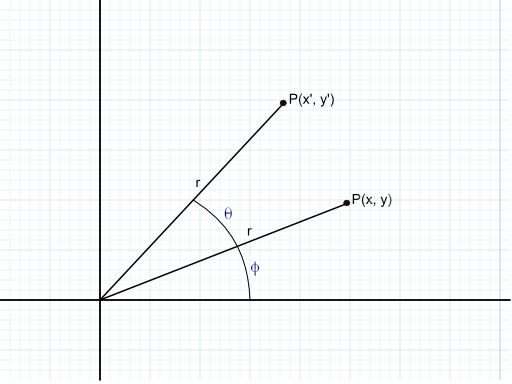

The coordinates x', y' could be derived using:


$$x' = x \cdot cos\theta - y \cdot sin\theta \\
y' = x \cdot sin\theta + y \cdot cos\theta
$$


Being a rotation about the origin, the distances from the origin for P and P' are the same. So we can write


$$x = r \cdot cos \phi \\
y = r \cdot sin \phi$$


And


$$x' = r \cdot cos(\theta + \phi) \\
y' = r \cdot sin(\theta + \phi)$$


 Keeping in mind the following trigonometric identities:


$$sin(\alpha + \beta) = sin(\alpha)cos(\beta) + cos(\alpha)sin(\beta) \\
cos(\alpha + \beta) = cos(\alpha)cos(\beta) - sin(\alpha)sin(\beta)$$


We can write 


$$x' = r \cdot cos(\theta)cos(\phi) - r \cdot sin(\theta)sin(\phi) \\
y' = r \cdot sin(\theta)cos(\phi) + r \cdot cos(\theta)sin(\phi)$$


Now we can write x', y' in term of x, y


$$x' = x \cdot cos(\theta) - y \cdot sin(\theta) \\
y' = x \cdot sin(\theta) + y \cdot cos(\theta)$$


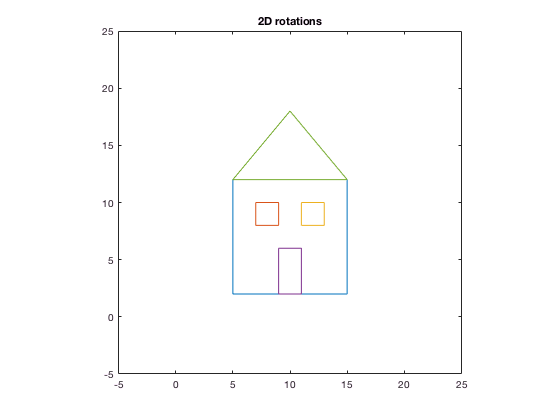

% === draw an house

% column vectors organised in matrixes, representing pieces to draw

S = [5 15 15 5 5; 2 2 12 12 2]; % wall
A = [9 11 11 9 9; 2 2 6 6 2];  % door
T = [7 9 9 7 7; 8 8 10 10 8]; % window
W = [11 13 13 11 11; 8 8 10 10 8]; % window
B = [5 15 10 5; 12 12 18 12]; % roof

plot(S(1,:), S(2,:), T(1,:), T(2,:), W(1,:), W(2,:),...
    A(1,:), A(2,:), B(1,:), B(2,:)),  axis equal, axis([-5 25 -5 25])

title('2D rotations')

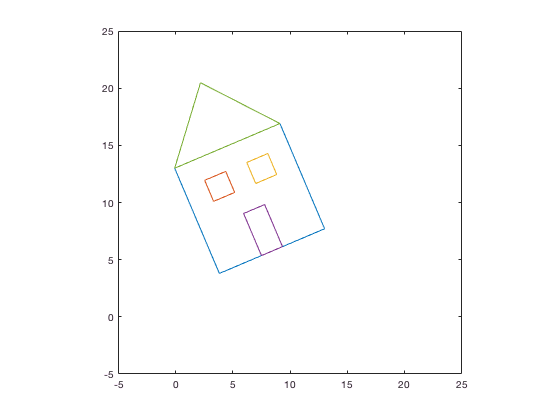

% == rotate 

t = 23; % degrees to rotate

% rotation matrix
R = [cosd(t),  -sind(t); sind(t), cosd(t)];

% apply transformation
S1 = R*S; B1 = R*B; A1 = R*A; W1 = R*W; T1 = R*T;

%plot
plot(S1(1,:), S1(2,:), T1(1,:), T1(2,:), W1(1,:), W1(2,:),...

    A1(1,:), A1(2,:), B1(1,:), B1(2,:) ), axis equal, axis([-5 25 -5 25])
